# LAB 10 : SAMPLING THEOREM

### Name: Purval Madhukar Bhude

### Roll No. S20230010193

### Section 4

## Question 1

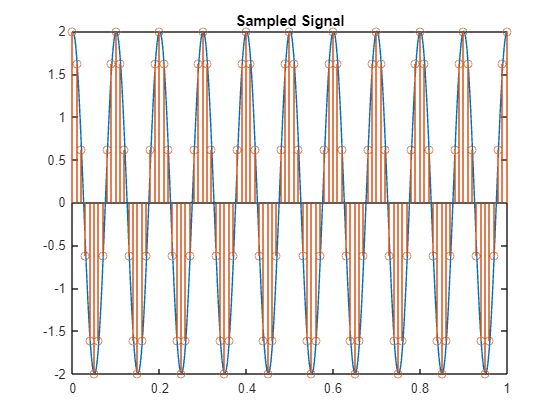

t=0:0.001:1;
n=0:0.01:1;
x = 2*cos(20*pi*t);
xn = 2*cos(20*pi*n);
plot(t,x);
hold on;
stem(n,xn);
title('Sampled Signal');
hold off;

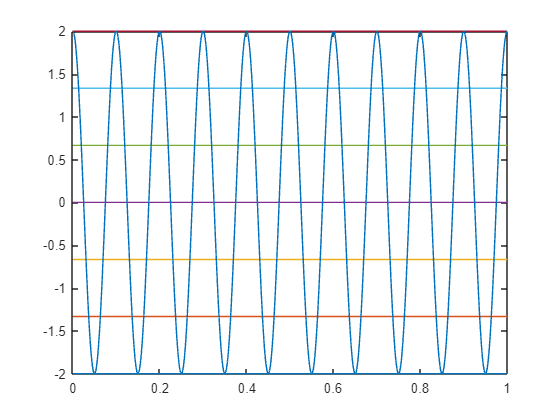

L = 7;
delta = (2-(-2))/(L-1);

for i=-2:delta:2
    k = i*ones(size(t));
    plot(t,k);
    hold on;
end
plot(t,x);
hold off;

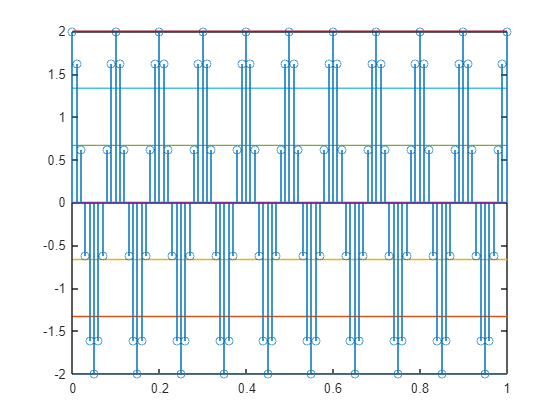

for i=-2:delta:2
    k = i*ones(size(t));
    plot(t,k);
    hold on;
end
stem(n,xn);
hold off;

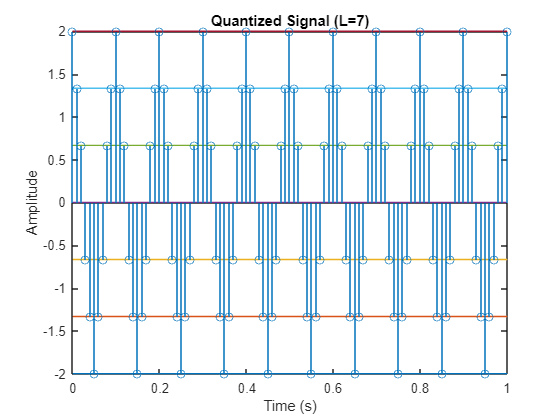

x_quantized = zeros(size(xn));
for i = 1:length(xn)
    [~, index] = min(abs(xn(i) - quant_levels));
    x_quantized(i) = quant_levels(index);
end
for i=-2:delta:2
    k = i*ones(size(t));
    plot(t,k);
    hold on;
end
stem(n, x_quantized);
hold off;
title('Quantized Signal (L=7)');
xlabel('Time (s)');
ylabel('Amplitude');

## Question 2

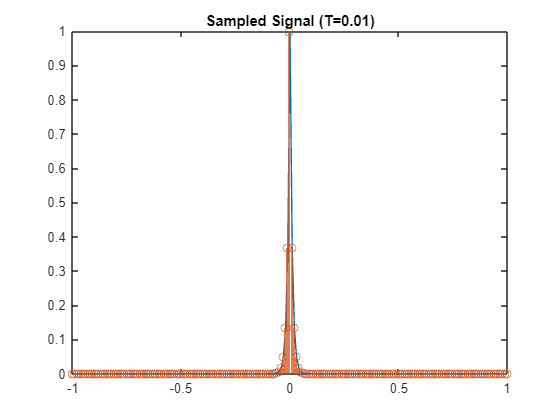

t=-1:0.01:1;
n=-1:0.01:1;
x = exp(-100*abs(t));
xn = exp(-100*abs(n));
plot(t,x);
hold on;
stem(n,xn);
title('Sampled Signal (T=0.01)');
hold off;

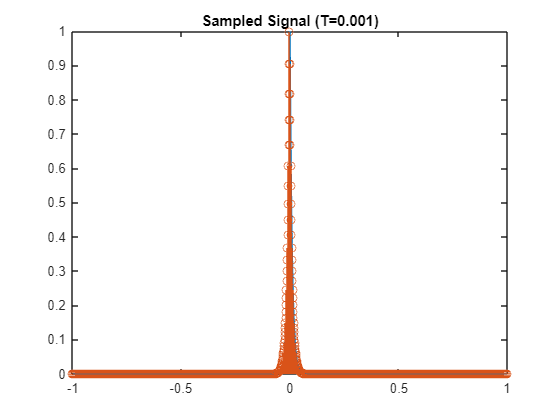

t=-1:0.001:1;
n=-1:0.001:1;
x = exp(-100*abs(t));
xn = exp(-100*abs(n));
plot(t,x);
hold on;
stem(n,xn);
title('Sampled Signal (T=0.001)');
hold off;